%% ==========================================================
%  Reliability Analysis (Non-MC Part)
%  - Figure 1: SNRI
%  - Figure 2: Frequency bias Delta f_j = f_j - fhat
%  - Figure 3: Normalized frequency bias |f_j - fhat| / f_j
%  - Table 1 : Average frequency bias
%  - Table 2 : Overall success rate based on Figure 1
% ==========================================================

close all; clc;
set(0,'DefaultFigureVisible','on');

%% ===== Parameters =====
tau1 = 1e-4;     % absolute tolerance for frequency bias figure / success criterion
tau2 = 0.01;     % normalized tolerance for normalized bias figure

% --- 1D SR ---
params_1d_emp = [1, 1];
params_1d_opt = [0.09, 0.01];

% --- 4D SR ---
params_4d_emp = [18, -10, 5, -3, 3, -5, 80, 15];
params_4d_opt = [18.70, -8.63, 6.63, -0.04, 7.87, -5.79, 80.54, 11.85];

%% ===== Frequency sweep =====
num_samples = 50;
fj_vals = logspace(-2.03, -1.98, num_samples)';

%% ===== Compute curves =====
[snri_1d_emp,bias_1d_emp, normbias_1d_emp, success_1d_emp] = ...
    run_reliability(params_1d_emp, false, fj_vals, tau1);

[snri_1d_opt,bias_1d_opt, normbias_1d_opt, success_1d_opt] = ...
    run_reliability(params_1d_opt, false, fj_vals, tau1);

[snri_4d_emp,bias_4d_emp, normbias_4d_emp, success_4d_emp] = ...
    run_reliability(params_4d_emp, true, fj_vals, tau1);

[snri_4d_opt,bias_4d_opt, normbias_4d_opt, success_4d_opt] = ...
    run_reliability(params_4d_opt, true, fj_vals, tau1);

abs_bias_1d_emp=abs(bias_1d_emp);
abs_bias_4d_emp=abs(bias_4d_emp);
abs_bias_1d_opt=abs(bias_1d_opt);
abs_bias_4d_opt=abs(bias_4d_opt);

%% ===== Average Frequency Bias Table =====
AvgBiasTable = table( ...
    [mean(abs_bias_1d_emp); mean(abs_bias_1d_opt); mean(abs_bias_4d_emp); mean(abs_bias_4d_opt)], ...
    'VariableNames', {'average_frequency_bias'}, ...
    'RowNames', {'1D empirical','1D optimal','4D empirical','4D optimal'} ...
);
disp('Mean absolute frequency bias: mean(|Delta f_j|)');

Average Frequency absoloutly Bias: mean(|Delta f_j|)


disp(AvgBiasTable);

                    average_frequency_bias
                    ______________________

    1D empirical          7.1726e-05      
    1D optimal            5.3527e-05      
    4D empirical          6.9645e-05      
    4D optimal            5.3042e-05      




%% ===== Overall Success Rate Table =====
SuccessTable = table( ...
    [success_1d_emp; success_1d_opt; success_4d_emp; success_4d_opt], ...
    'VariableNames', {'success_rate'}, ...
    'RowNames', {'1D empirical','1D optimal','4D empirical','4D optimal'} ...
);
disp('Success Rate based on Figure 1 criterion: |Delta f_j| <= tau1');

Success Rate based on Figure 1 criterion: |Delta f_j| <= tau1


disp(SuccessTable);

                    success_rate
                    ____________

    1D empirical        0.84    
    1D optimal          0.92    
    4D empirical        0.66    
    4D optimal             1    



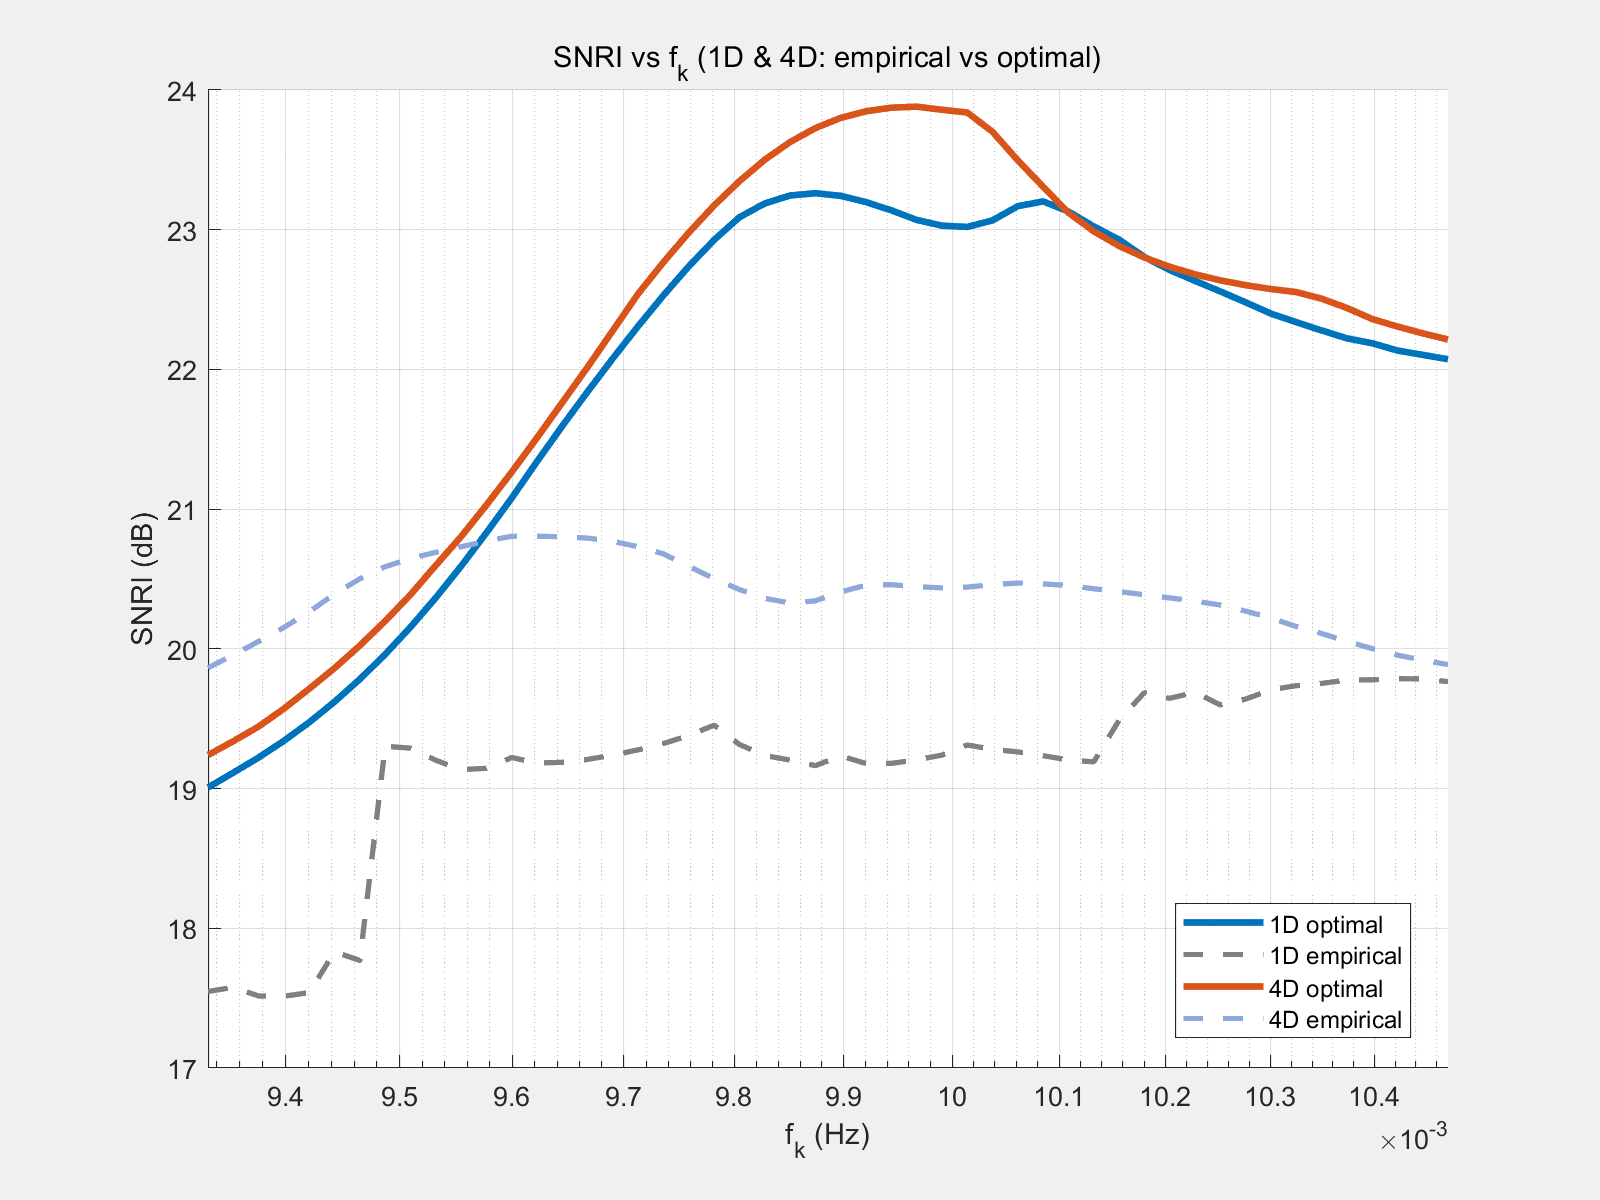


%% ===== Colors =====
col_1d_opt = [0.00 0.45 0.74];   % #0072BD
col_4d_opt = [0.85 0.33 0.10];   % #D95319
col_1d_emp = [0.50 0.50 0.50];   % #7E7E7E
col_4d_emp = [0.56 0.66 0.86];   % #8FAADC

col_tau = [0.49 0.18 0.56];

%% =======================
%   FIGURE 1 — SNRI
% =======================
f1 = figure('Name','SNRI Comparison', ...
            'NumberTitle','off', ...
            'Position',[200 200 800 600], ...
            'MenuBar','figure', ...  
            'ToolBar','figure');    

hold on;
plot(fj_vals, snri_1d_opt, '-',  'LineWidth', 2.5, 'Color', col_1d_opt);
plot(fj_vals, snri_1d_emp, '--', 'LineWidth', 2.0, 'Color', col_1d_emp);
plot(fj_vals, snri_4d_opt, '-',  'LineWidth', 2.5, 'Color', col_4d_opt);
plot(fj_vals, snri_4d_emp, '--', 'LineWidth', 2.0, 'Color', col_4d_emp);

set(gca,'XScale','log');
grid on;
xlabel('f_j (Hz)');
ylabel('SNRI (dB)');
title('SNRI vs f_j (1D & 4D: empirical vs optimal)');

legend({'1D optimal','1D empirical','4D optimal','4D empirical'}, 'Location','best');

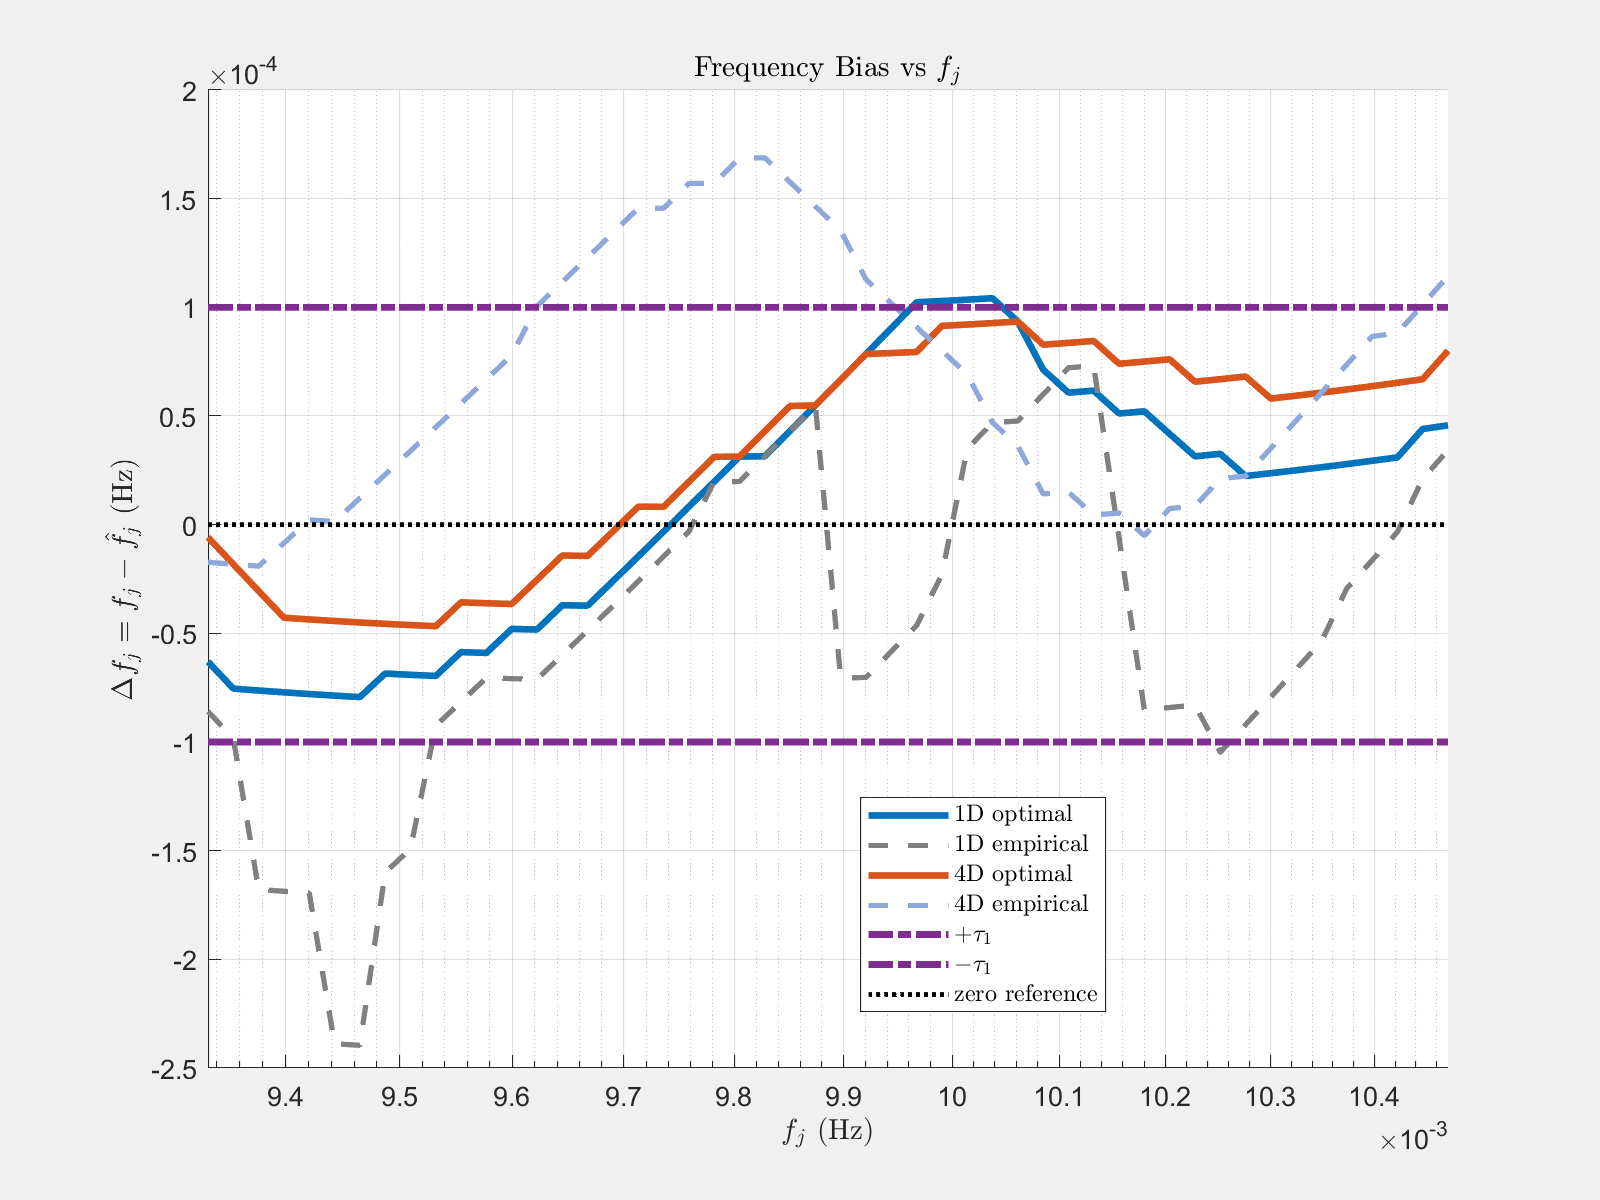


%% =======================
%   FIGURE 2 — Frequency Bias
% =======================
figure('Name','Frequency Bias', ...
       'NumberTitle','off', ...
       'Position',[200 200 800 600], ...
       'MenuBar','figure', ...
       'ToolBar','figure');
hold on;

plot(fj_vals, bias_1d_opt, '-',  'LineWidth',2.5, 'Color',col_1d_opt);
plot(fj_vals, bias_1d_emp, '--', 'LineWidth',2.0, 'Color',col_1d_emp);
plot(fj_vals, bias_4d_opt, '-',  'LineWidth',2.5, 'Color',col_4d_opt);
plot(fj_vals, bias_4d_emp, '--', 'LineWidth',2.0, 'Color',col_4d_emp);

plot(fj_vals,  tau1 * ones(size(fj_vals)), '-.', 'LineWidth',2.6, 'Color',col_tau);
plot(fj_vals, -tau1 * ones(size(fj_vals)), '-.', 'LineWidth',2.6, 'Color',col_tau);
plot(fj_vals, zeros(size(fj_vals)), ':', 'LineWidth',1.8, 'Color',[0 0 0]);

set(gca,'XScale','log');
grid on;

xlabel('$f_j\ \mathrm{(Hz)}$','Interpreter','latex');
ylabel('$\Delta f_j = f_j - \hat{f}_j\ \mathrm{(Hz)}$','Interpreter','latex');
title('Frequency Bias vs $f_j$','Interpreter','latex');

legend({'1D optimal','1D empirical','4D optimal','4D empirical', ...
        '$+\tau_1$','$-\tau_1$','zero reference'}, ...
       'Location','best','Interpreter','latex');

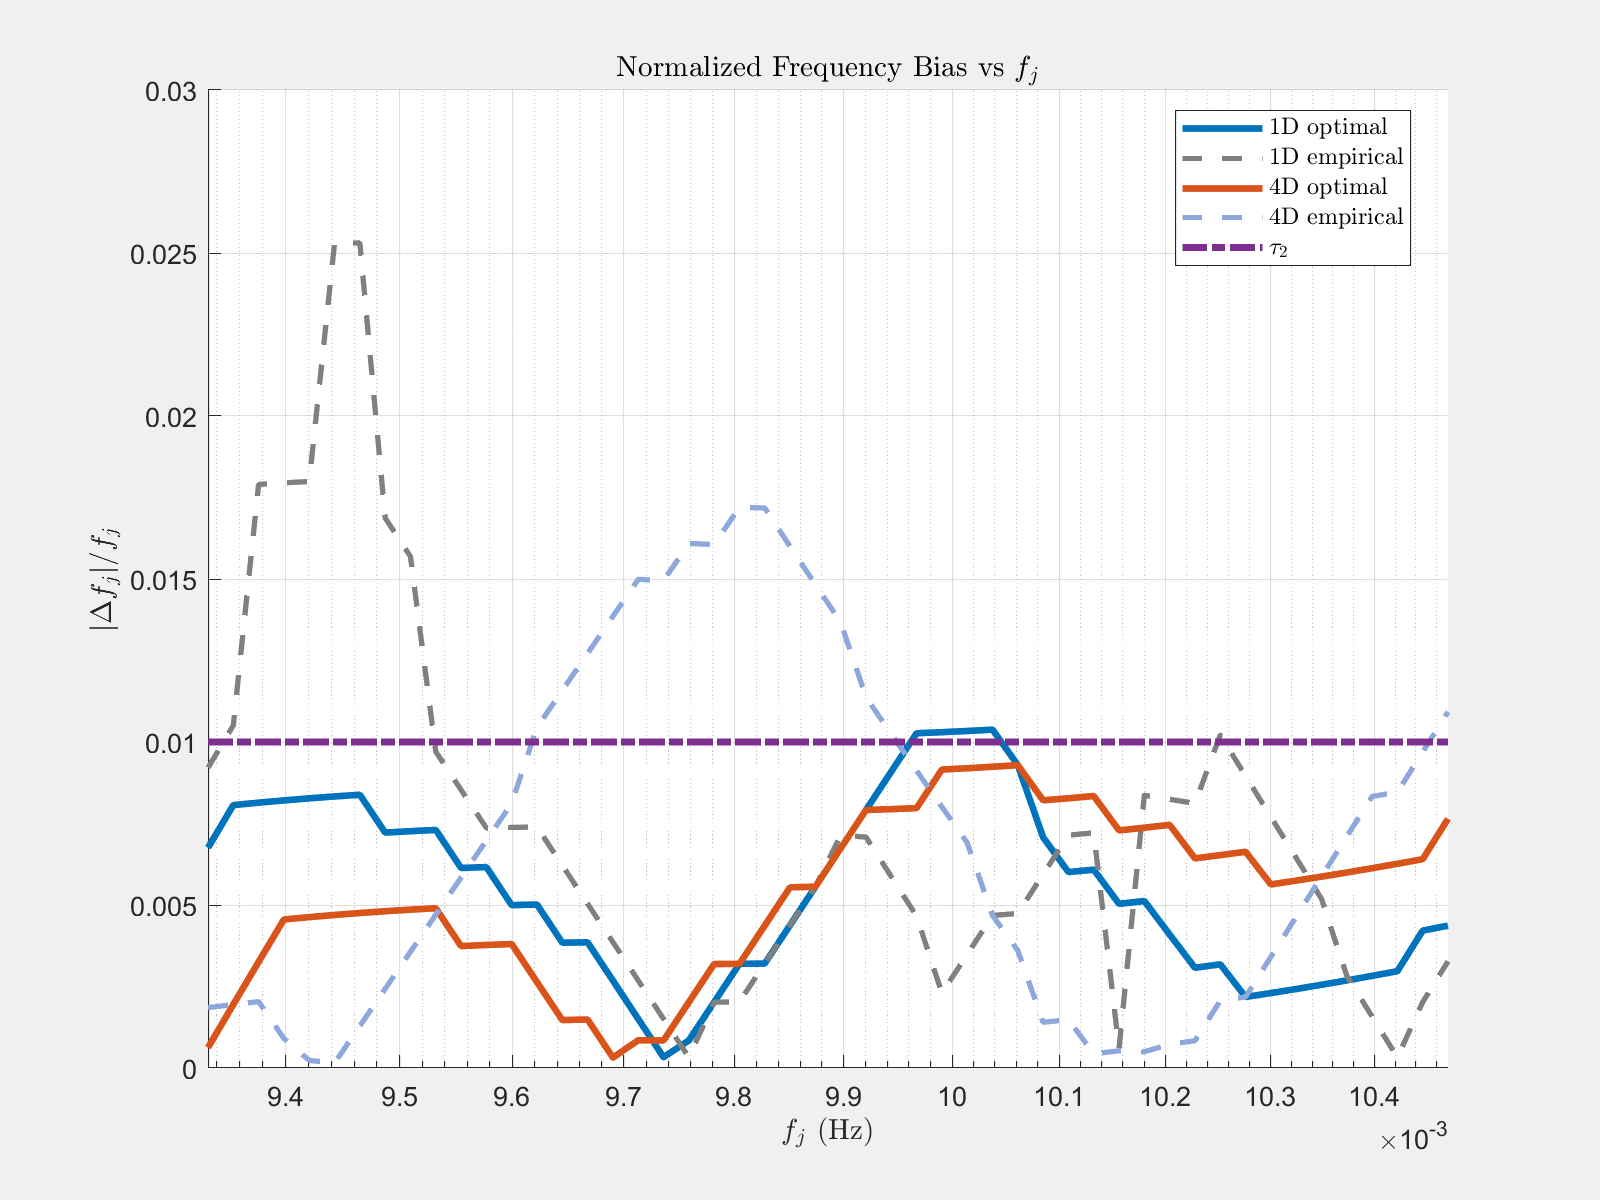


%% =======================
%   FIGURE 3 — Normalized Frequency Bias
% =======================
figure('Name','Normalized Frequency Bias', ...
       'NumberTitle','off', ...
       'Position',[200 200 800 600], ...
       'MenuBar','figure', ...
       'ToolBar','figure');
hold on;

plot(fj_vals, normbias_1d_opt, '-',  'LineWidth',2.5, 'Color',col_1d_opt);
plot(fj_vals, normbias_1d_emp, '--', 'LineWidth',2.0, 'Color',col_1d_emp);
plot(fj_vals, normbias_4d_opt, '-',  'LineWidth',2.5, 'Color',col_4d_opt);
plot(fj_vals, normbias_4d_emp, '--', 'LineWidth',2.0, 'Color',col_4d_emp);

plot(fj_vals, tau2 * ones(size(fj_vals)), '-.', 'LineWidth',2.6, 'Color',col_tau);

set(gca,'XScale','log');
grid on;

xlabel('$f_j\ \mathrm{(Hz)}$','Interpreter','latex');
ylabel('$|\Delta f_j|/f_j$','Interpreter','latex');
title('Normalized Frequency Bias vs $f_j$','Interpreter','latex');

legend({'1D optimal','1D empirical','4D optimal','4D empirical','$\tau_2$'}, ...
       'Location','best','Interpreter','latex');